# Testing our function generator

Brian Rasnow 10 Nov 22

## Objective

We will debug as necessary our function generator, using our Arduino (running oscope1.ino) and Matlab's' oscope1.m to display its output. We'll implement several modifications of oscope1.m to display a more stable waveform, display amplitudes, frequency *and* phase difference between the A0 and A1 inputs. We'll also address and correct the fact that A0 and A1 aren't simultaneously measured.

## Function generator prerequisites

- We should test that the XR2206 function generator is likely working. Set the 3 pots in the middle of their range (vertical slot), one jumper on sine, and the frequency jumper in the middel (3rd) position. The DVM should read on the sine wave output (bottom; ground is top) ~6VDC, 1.4VAC, the AC voltage should respond to the amplitude pot (note: the amplitude pot is wired backwards on my function generator, so the AC voltage increases by turning the pot unconventionally counter-clockwise -- ). My DVM won't measure frequency on the Sine output. 

- Move the red voltmeter probe to the square wave output (middle), and I read ~6.8VDC, 5.5VAC, and hitting the select button again to measure Hz, I always get zero. To measure frequency, switch the main dial to Hz and I see ~300Hz, and who's value changes with the Fine and Course frequency pots. Move the frequency jumper up and down, so you know which way increases and decreases the center frequency. 

## Arduino prerequisites

In the IDE, upload the LM317controller and verify its working, you can do this with a few p <0-255> commands to set a pwm value and verify the value with your DVM on volts DC. (We won't use the LM317 control circuit yet, but we'll see later how we can use it to also control the function generator frequency from software).

Arduino ground is connected to function generator and power supply ground via 2 jumpers to the blue rails (the USB which powers the Arduino may have a floating ground relative to your apparatus, so they need to be connected).  

## 1. New Hardware Interface

Our function generator produces outputs between 0-12V, so we'll need a voltage divider between it and the Arduino and add a 10k resistor as our "probe" for extra protection. Anticipating two channels, connect the output to both A0 and A1. I used two "probe" lines with 10k resistors soldered to one end (white horizontal jumpers in above photo). NOTE: remember to unplug the LM317 from the top red row if it is there. I plugged the LM317 output into an unused breadboard column so the pin wouldn't accidently touch something else (Fig. 1 red wire in top column 3; voltage divider is column 4 -- in hindsight it is safer to move them a few columns apart).

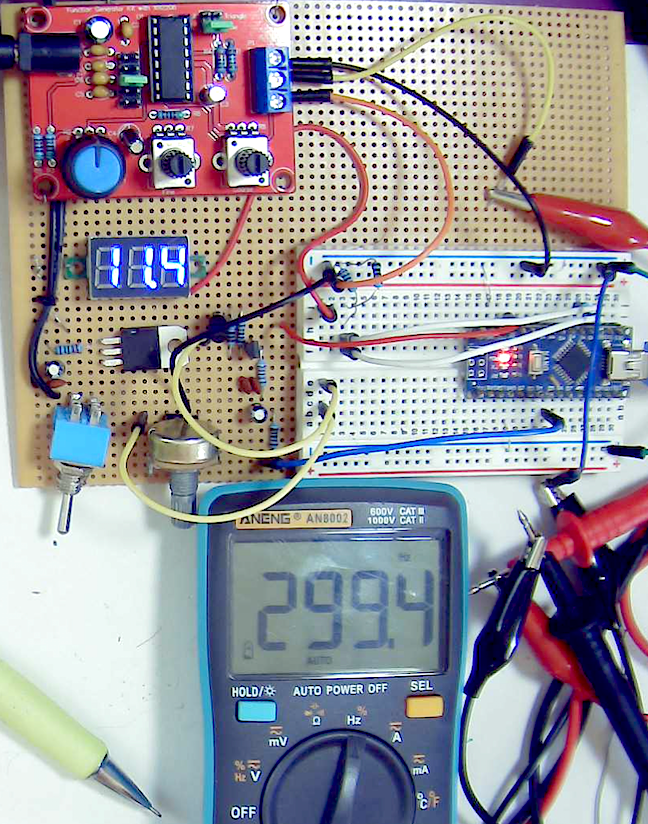

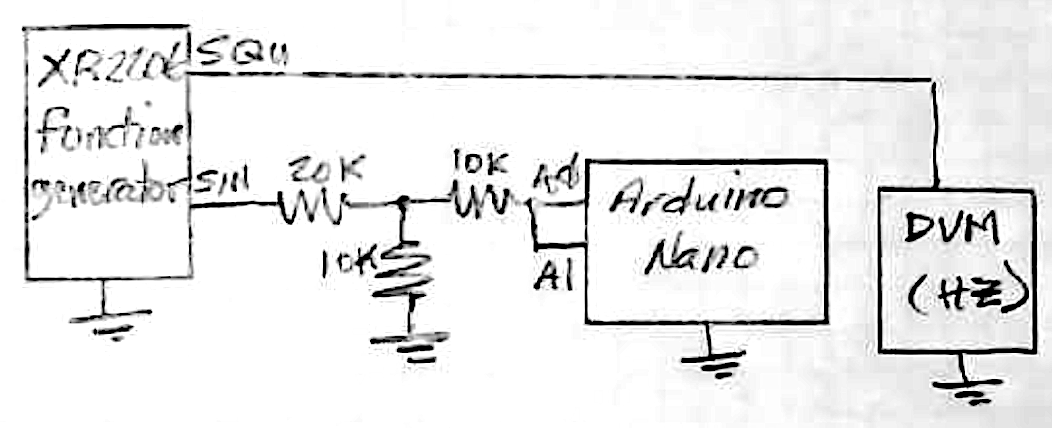

    Figure 1. Red and black clip leads attach the DVM to ground and Square output (yellow wire to red clip lead in upper center). Function generator sine wave drives a voltage divider (x1/3) connected to A0 and A1 each through 10k resistors (horizontal white wires on solderless breadboard). Make sure to connect a common ground between the Arduino, voltage divider, and function generator. The reason we're measuring the same voltage twice on A0 and A1 is to calibrate a 2-channel oscilloscope.   

## 2. Arduino software

Arduino is running `oscope1.ino` as written weeks ago. This code responds to two commands:` p <pwmValue = 0:255> analogWrite`'s the value to pin D5, and the `b` command returns a buffer of 400 consecutive `analogReads` of A0 and A1 appended with the elapsed time.

## 3. Matlab software

### 3.1 Connecting to the Arduino

Connecting to the Arduino was documented in `matlabControlOfArduino2.mlx` a couple weeks ago. I just searched [www.mathworks.com](http://www.mathworks.com) for how to determine the operating system and found: 

system_dependent('getos')

So we could make a somewhat generic initialization routine that could automate port identification ... but I'll leave that up to you if you want. I'm just going to hard code what works for me on my Macbook. Before executing this, remember to free the Arduino from the IDE. Here's our prior oscope1.m:

%% script oscope1.m -- first version of an Arduino oscilloscope display
% 16oct22 BR, Arduino running oscope1, command set = b, p, s
if ~exist('runBtn','var') % add the button once

ans = 'Darwin 19.6.0 Darwin Kernel Version 19.6.0: Mon Aug 31 22:12:52 PDT 2020; root:xnu-6153.141.2~1/RELEASE_X86_64 x86_64'

    runBtn = uicontrol('style','radiobutton','string','run','units', ...
        'normalized','position',[.13 .93 .1 .04]);
    runBtn.Callback = 'oscope1';
end
if ~exist('ard','var') % initalize arduino
    disp('initializing arduino ...')
    ports = serialportlist;
    ard = serialport(ports{end},115200);
    ard.Timeout = 2;
    configureTerminator(ard, 0);
    clear ports;
    pause(2); % time to boot
end
if ~exist('runOnce','var'), runOnce = true; end

while runBtn.Value || runOnce
    writeline(ard,'b'); 
    try
        bin = read(ard,804,'int16');
        dt = bitshift(bin(802),16)+bin(801); % microseconds
        data = reshape(bin(1:800),2,400)' - 1;
        t = linspace(0,dt/1000,400)'; % calibrate the time axis
    catch
        flush(ard);
        break;
    end
    try   % change data inside the plot is faster
        set(plotHandle(1),'XData',t,'YData',data(:,1));
        set(plotHandle(2),'XData',t,'YData',data(:,2));
    catch
        plotHandle = plot(t, data, '.-');
        xlabel('msec'); ylabel('ADU')
        legend('A0','A1'); grid on;
    end
    displayfps;
    drawnow;
    runOnce = false;
end


The first if block makes the `runBtn` (once) on the figure window to control triggering. The second block initializes the Arduino once, the 3rd if statement initializes the `runOnce` variable so we can trigger an acquisition from the command line (or by clicking the `runBtn`). The business part happens inside the `while` loop: send a 'b' to the Arduino, then read the buffer into variable `bin`. extract the elapsed time `dt`, reshape the `data` into two columns, [A0 A1], and make a calibrated time vector `t`. If an error occurs among these commands, `flush` (empty -- think toilet) the serial buffer and try again. The next `try/catch` construct is for displaying the data. Fastest is to just change the `XData` and `YData` inside the existing plot (if there is one), but if that generates an error, then make a new plot. Finally, displayfps (frames per second), force a redraw, and set runOnce to false so the while loop only runs once. Fairly self-commenting code??

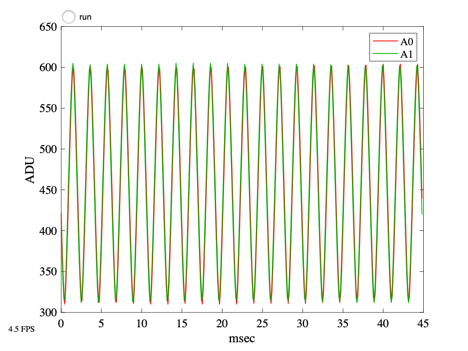

    Figure 2. Run button (top left) and frames per second display (bottom left)

Note that Matlab can be sluggish while the runBtn is on because it's doing a lot of work updating the figure several times per second. If you're not able to get a sine wave display like above, then go back and debug ... look at the error messages, e.g., maybe displayfps isn't found in your path. In the command window, query ard: is the Port your arduino? Can you write e.g., 'p 150' command and change D5 or the LM317 voltage (if connected to D5)? Or

 >> volts2pwm(5,ard); % does LM317 respond?

Troubleshooting is all about divide and conquer -- of all the critical code and hardware you've built, can you determine what works and what doesn't, and narrow the "doesn't" until you find the bug.

### 3.2 Triggering

One annoying feature of this oscilloscope display is that the initial phase jumps around, perhaps randomly or drifts. It behaves like a "free-running" oscilloscope. Oscilloscopes have "trigger" circuits so repetitive waveforms are repeated at the same phase or starting slope. The following function trims the data to always begin with the same initial threshold crossing, and it does a bit more too, returning not just trimmed data but the number of periods: 

This function demonstrates a software "design pattern" I've found very useful: 

- Check arguments and set default values (the 3 `if` statements, `nargin` is an automatic variable containing the number of input arguments. So if `trim` is called with less than 4 arguments, we need to assign a default value for the reference channel which is used to trigger, and in this case it is assigned to the last channel or A1. 

- The next blocks of code do the work of trimming ... here's how: `a` is a boolean vector = true when the reference channel is greater than threshold, and false otherwise. b is shifted one sample in time, i.e., the first element of `b` is the second element of a, and the last b is the first a, (to keep them the same size). b-a is the difference of two booleans, so each element is either -1, 0, or 1, the 1's are located where the threshold is crossed from negative to positive (you may need to draw some pictures to see why that is). The find function returns the indicies (locations) of the positive threshold crossings and puts them in p0x. The last part does the trimming into d. 

- The 3rd part of the design pattern is preparing the output. If the automatic variable nargout indicates 2 return values, then we return the number of periods, along with the trimmed data. From the number of periods, we can compute the frequency, which is a critical parameter for subsequent Fourier analysis that we'll do later. What threshold should we use? where the slope is steepest will give us the least jitter, and that's around 500 ADU on my system.

Save this function in your toolbox as `trim.m`, then modify `oscope1.m` to call it (and save as `oscope2.m`). Here's a sneaky way to include `trim` by only changing a few lines of `oscope1`: rename `data` --> `rawdata`, and let `trim` return `data`. `plot` will throw an error if its two arguments are different lengths, so we must trim the time vector too:

rawdata = reshape(bin(1:800),2,400)' - 1;
[data, npds] = trim(rawdata, 450); % adjust 2nd arg = ADU with steepest slope
t = linspace(0,dt/1000,400)';
t = t(1:length(data));

 Before saving this modified file as oscope2, we need to also change runBtn's callback, then Save As ... oscope2.m

    runBtn.Callback = 'oscope2';

Click the run button, and the frame rate hasn't changed, but the initial phase is now stable just below the 500 ADU threshold, and the final phase is also stable -- almost have to tweak the amplitude or frequency knobs to see a change. Now when I turn the amplitude too low (high), trim throws an error -- because there were no threshold crossings. Changing the threshold to 460, saving, and toggling off and on the run button, now lets me reduce the amplitude to a minimum, corresponding to ~440-480ADU -- your numbers may vary a bit from those. 

### 3.3. Measuring Frequency 

An argument could be made to do this in the Arduino hardware: the square wave would have to be reduced to <5V, and its period measured with Arduino's built-in `pulseIn()` function, or it could trigger an interrupt and an interrupt service routine (ISR) could read the time with `micros();`. 

**Question: The square wave output of the function generator has an amplifude ~12V. A) Draw a schematic showing  how could you would connect it to the Arduino. B) Which inputs would you have to connect it to in order to use interrupts?**

But I prefer leaving the Arduino programmed as is and computing the frequency in Matlab. I'm much more productive programming in Matlab's higher level language and interpreted environment than writing and compiling C in Arduino's IDE. 

We can compute the frequency from the sample rate, number of samples, and number of periods, as follows. How did I come up with these equations? How might you come up with them? Dimensional analysis is a great tool -- the units of frequency are Hz = 1/time, so we want number of periods / their duration. 

sr = length(rawdata)/dt*1e6; % sample rate (#/sec)
freq = sr/(length(data)/npds); % Hz, 1/sec
sprintf('%.1fHz',freq)

**Question: Explain why the sample rate and  frequency are given by the above formulas, using conversion factors. (Conversion factors are ratios who's numerators equal denominators, i.e., they are equal to 1, but they have units, e.g., (1e6 microseconds/1 second) when multiplied by seconds results in microseconds. **

Connect your DVM to the Square wave output, set the main dial to Hz. How well do the two agree?

**Question: Which one do you think is more accurate? Why?? **

**Exercise: Show the frequency in the title of of the figure.**

### 3.4. Measuring Amplitude in the Time Domain

Without proving it, I'll just state that the amplitude of our waveforms (assuming they are noise-free sine waves), is simply given by:   


vdvm = 2.500; % vac on dvm
vref = 4.59; % vdc on dvm
vard = mrms(data) * vref / 1023 * 3; % multiply by voltage divider (20k+10k)/10k

ans = '312.0Hz'

[vard vdvm]
err = (vard - vdvm) / vdvm 

2.7% difference between Arduino and DVM is a little big but doesn't raise warning flags that something is terribly wrong. E.g., is the voltage divider ratio exactly 3? A problem with mrms is that it destroys any phase information (by summing over time), and it also doesn't do a great job of rejecting noise. 

### 3.5 Measuring Amplitude and Phase with the Fourier Transform

The (Fast) Fourier transform (`fft`) converts time domain waveforms into (complex) amplitudes (and phases) vs. frequency. The first frequency is zero Hz or DC, equal to the mean of the signal. With `npds` in the time domain, we expect the amplitude to be the `npds+1` Fourier component. This has to be normalized into ADUs as follows (it took some effort to find/test these formulas):  

fd = fft(data); % data is trimmed to npds 
ampl = abs(fd(npds+1,:)) / length(data) * 2

How does that compare with mrms (the above is in ADU units)?

err = (ampl - mrms(data)*sqrt(2))./ampl

The Fourier amplitudes are .2% lower (and probably more accurate because noise at all other frequencies contribute to the mrms values). 

Phase is given in radians with angle, let's convert it to degrees: 

theta = rad2deg(angle(fd(npds+1,:))), diff(theta)

ans =     2.5684    2.5678    2.5000


The phase of each waveform is somewhat arbitrary -- related to the threshold we picked and the amplitude, but the difference in phase between the channels is what will have significance when we're not measuring the same waveform. Here we see a significant phase difference between A0 and A1 (which are the *identical* signal) -- and I hope you're saying, "Ahhh! That's because .....

Before moving on, let's add the amplitudes and phases to the title: 

sprintf('%.2fHz V1=%.2f V2 = %.2f deg=%.2f',freq, ampl, diff(theta))

err =     0.0273    0.0271


Adding all this to the title requires shrinking the font: 

plotHandle(3) = title(sprintf('%.2fHz V1=%.2f V2 = %.2f deg=%.2f', ...
            freq, ampl, diff(theta)),'FontSize',12);

ampl =   269.2537  269.1848


I put all these changes into `oscope2`, Saved As ... `oscope3.m`, and ... it didn't work ... until I edited `runBtn.Callback = 'oscope3';` It's so easy to forget key details.... 

### 3.6 Temporal skewing and deskewing

So hopefully you've noticed that the phase angle (`deg` in the title) increases with frequency, and it *shouldn't *because V1 and V2 are the same waveforms. What's going on?

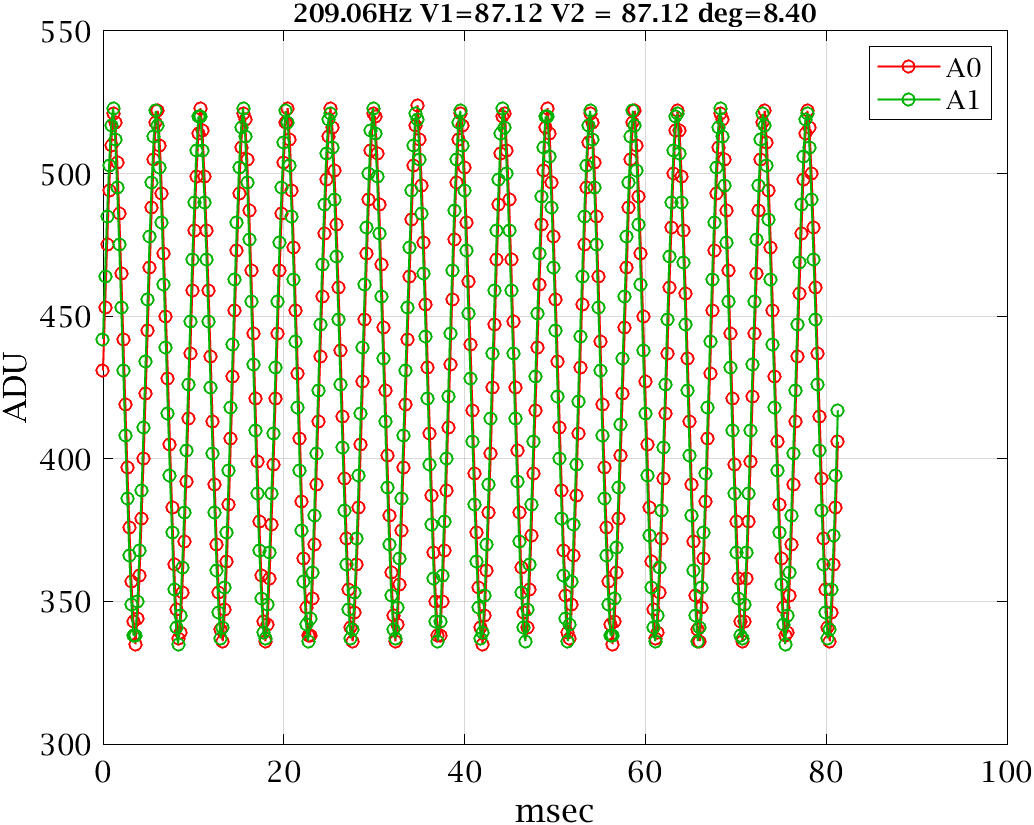

    Figure 3. A0 and A1 datapoints are clearly interleaved, or said another way, A1 is *skewed* or shifted in time relative to A0. 

Especially if you change the plot style, `>> dots('o');` as shown above, the data are not identical, as the schematic would suggest. A0 and A1 are measuring the same voltage, but at different times or phases. The Arduino software clearly reflects this: A0 is read, then A1, then A0, ... the data are interleaved in time, resulting in a temporal shift (or "skew") between A0 and A1. How serious is this depends on the frequency we're measuring. The RMS amplitudes are the same to within 4 significant figures, but what's the rms of the difference?  

mrms([data data(:,2)-data(:,1)])

err =    -0.0022   -0.0022


Just noticed my function generator amplitude was low so these numbers are small. But we see the rms amplitude of A0 and A1 are very similar but the difference is HUGELY big: 

err = [ans(1)-ans(2) ans(3)] /ans(1)

theta =  -108.2012  -95.8263


ans = 12.3749

Less than 0.1%  difference between rms amplitudes of A0 and A1, but the difference in the waveforms is a huge 15% of the signal, instead of zero! 

So what to do? First, recognize this is the beauty of systematic errors. They are predictable, vs. noise which is by definition unpredictable or random. When you have a systematic error, like temporal skew, you can model a new "system" that takes undoes the error. Let's try to model the error this way. Imagine a sample clock that ticks each time analogRead is called: 1 = analogRead(A0), 2 = analogRead(A1), 3 = analogRead(A0), etc. This clock ticks: 

tt = (1:numel(data))'; 

ans = '306.22Hz V1=269.25 V2 = 269.18 deg=12.37'

All the A0's are measured on odd t's and all the A1's are measured on even t's. Saying that in code, data(:,2) was measured at times t(2:2:end), and data(:,1) was measured at times t(1:2:end);. If we "remeasure" data(:,2) at t(1:2:end), then we fixed the skew ... and Matlab has a function that does that: 

>> help spline

 spline Cubic spline data interpolation.

    YQ = spline(X,Y,XQ) performs cubic spline interpolation using the

    values Y at sample points X to find interpolated values YQ at the query

    points XQ.

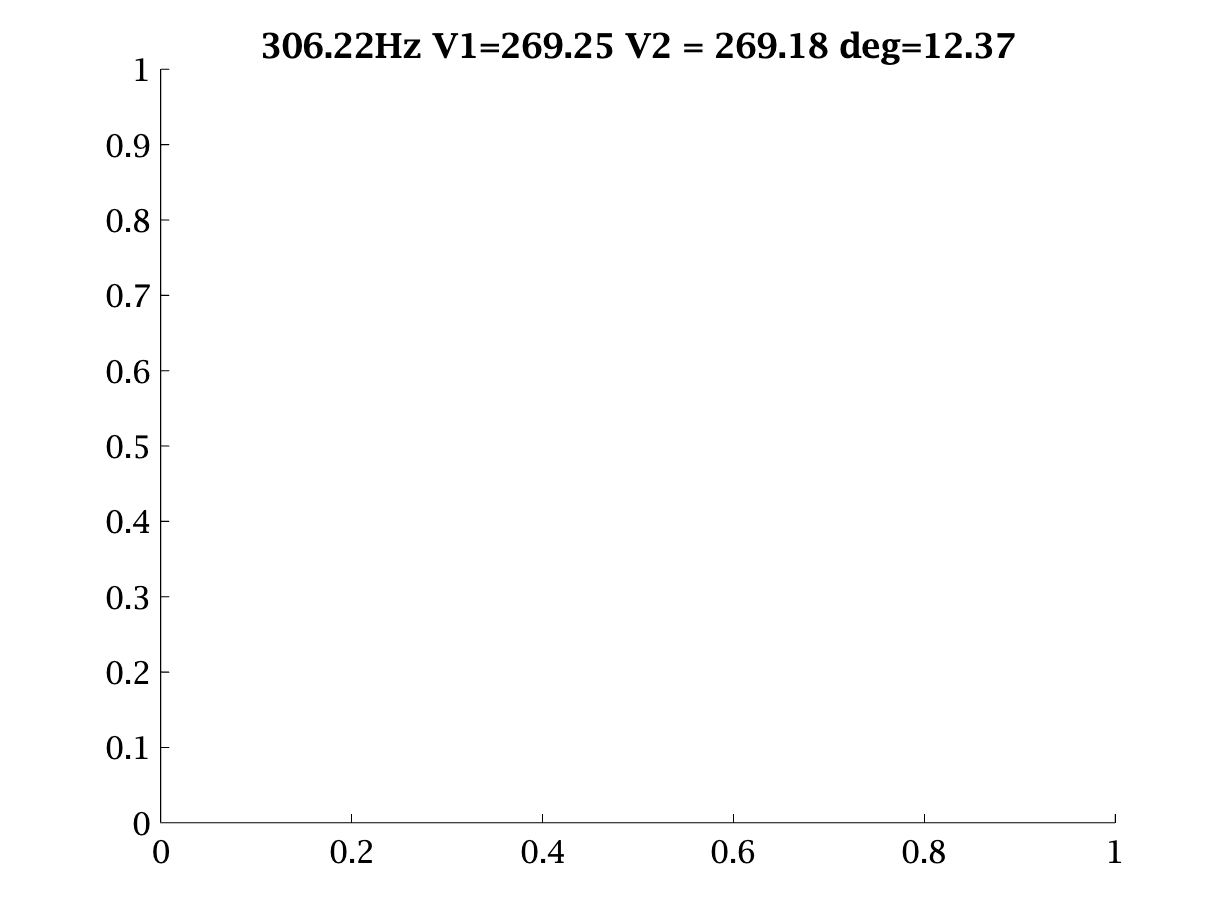

deskewedA1 = spline(tt(2:2:end),data(:,2),tt(1:2:end));
plot(tt(1:2:end), data, 'o-', tt(1:2:end),deskewedA1, '.')

legend('A0','A1','deskewedA1')

    Figure 4. Deskewing A1 (blue dots) makes it (appear) concurrent with A0. 

The spline moved the green data points into the red dots ... removing most of the systematic error. Let's quantify how much error is left, and we can use the same error calcs we did above by overwriting data(:,2) with its deskewed version:

data(:,2) = deskewedA1;

ans =    61.6999   61.6961    9.1680


mrms([data data(:,2)-data(:,1)])
err = [ans(1)-ans(2) ans(3)] /ans(1)

err =     0.0001    0.1486


That reduced the rms difference to ~1/2 ADU -- can't expect to do much better (at least in the time domain ;-). 

**Exercise: Add the deskewing code into oscope2 and save the resulting script as oscope3.m. Hint: don't forget to change  runBtn.callback. **

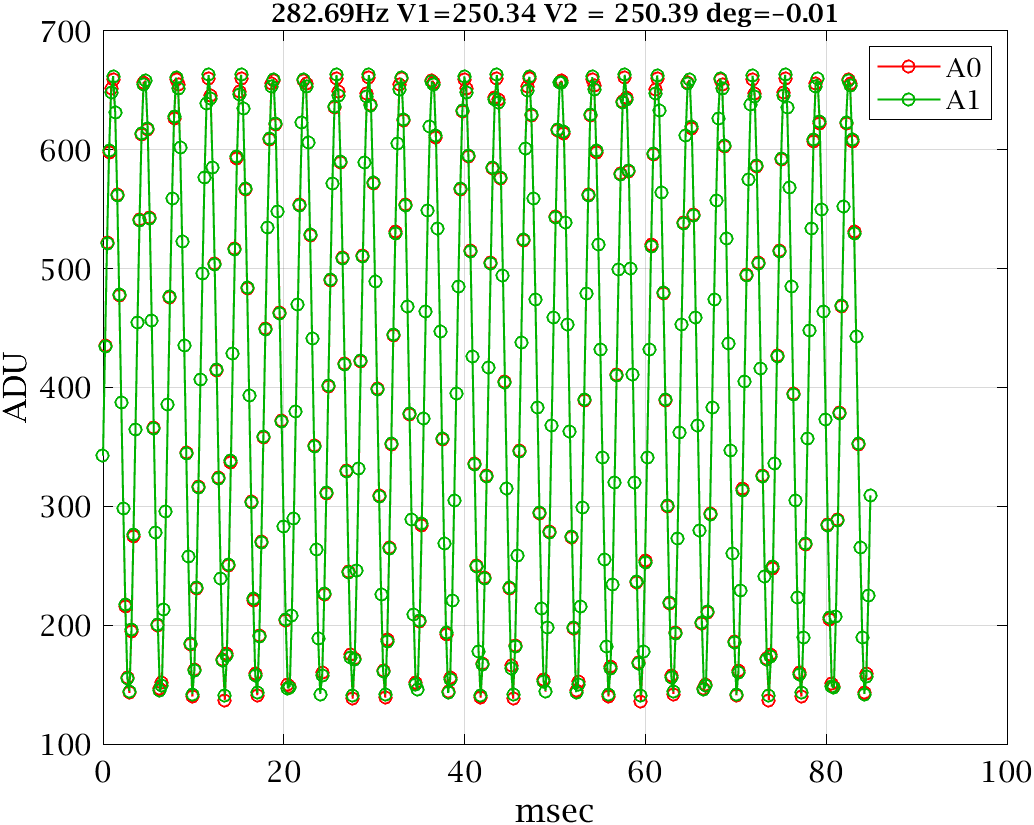

    Figure 5. Display of oscope3. Note, after running `>> dots('o') `once, the setting stuck because `plot` hasn't been called again, only 3 handles change with each figure update.

The green A1 datapoints now almost completely occlude (sit on top of, identical to) the red A0 data -- we did it!! We undid a systematic error by using digital signal processing (in particular, `spline`) to remove the temporal skewing artifacts. Later we'll explore another algorithm to deskew A1 in the frequency domain. 

BTW, I've noticed that sometimes, e.g., after I wake up the computer from sleep, the graph doesn't update, and I need to cycle the run button a couple of times. Matlab has a graphics bug when awaking with a 2nd monitor connected to a laptop.

## Results

Here's my final version of oscope3. I hope you don't blindly copy/paste it, but take time to understand/appreciate what each line of code does. A difficulty with learning software, and electronics is that code and schematics don't reveal their history. How they were built piece by piece is lost. When you see the whole thing, it's overwhelming. But if you could unwrap how it was built, little by little, tweak by tweak, it would be much easier to understand. 

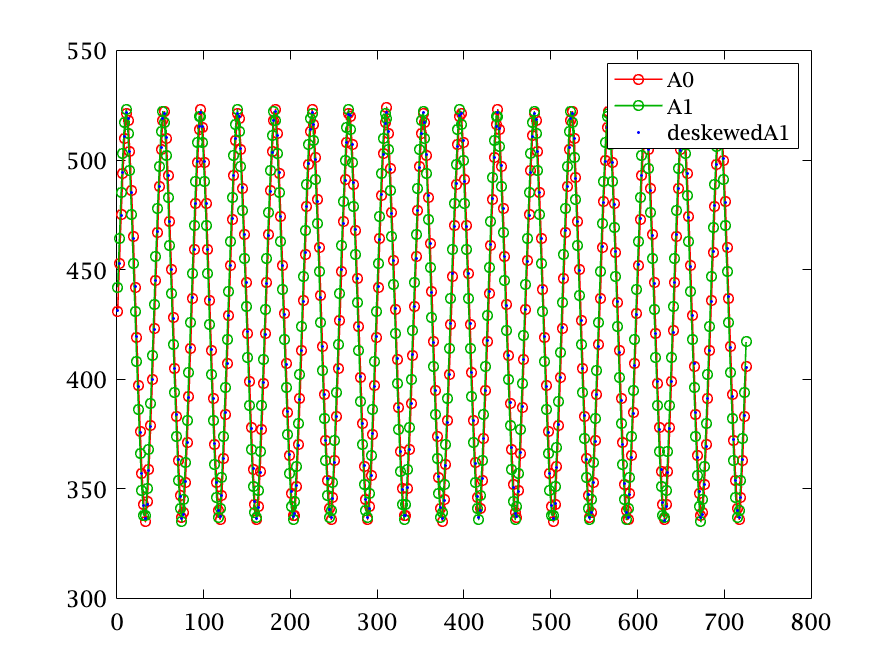

%% oscope3.m -- added title with freq, ampls, phase diff, and spline deskew
%% oscope2.m -- added trim for triggering
%% script oscope1.m -- first version of an Arduino oscilloscope display
% 16oct22 BR, Arduino running oscope1, command set = b, p
if ~exist('runBtn','var') || ~isvalid(runBtn)  % add the button once
    runBtn = uicontrol('style','radiobutton','string','run','units', ...
        'normalized','position',[.13 .93 .1 .04]);
    runBtn.Callback = 'oscope3';
end
if ~exist('ard','var') % initalize arduino
    disp('initializing arduino ...')
    ports = serialportlist; % on my computer, arduino is always the last one

    ard = serialport(ports{end},115200);
    ard.Timeout = 2;
    configureTerminator(ard, 0);
    clear ports;
    pause(2); % time to boot

ans =    61.6999   61.6936    0.5492


end

err =     0.0001    0.0089


if ~exist('runOnce','var'), runOnce = true; end

while runBtn.Value || runOnce
    writeline(ard,'b'); 
    try
        bin = read(ard,804,'int16');
        dt = bitshift(bin(802),16)+bin(801); % microseconds
        rawdata = reshape(bin(1:800),2,400)' - 1;
        [data, npds] = trim(rawdata, 450); % adjust 2nd arg = ADU with steepest slope
        t = linspace(0,dt/1000,400)';
        t = t(1:length(data)); 
        sr = length(rawdata)/dt*1e6; % sample rate (#/sec)
        freq = sr/(length(data)/npds); % Hz, 1/sec
        tt = (1:numel(data))'; % deskew
        data(:,2) = spline(tt(2:2:end),data(:,2),tt(1:2:end));
        fd = fft(data); % data is trimmed to npds 
        ampl = abs(fd(npds+1,:)) / length(data) * 2;
        theta = dangle(fd(npds+1,:));
    catch
        flush(ard);
        break;
    end
    try   % change data inside the plot is faster
        set(plotHandle(1),'XData',t,'YData',data(:,1));
        set(plotHandle(2),'XData',t,'YData',data(:,2));
        plotHandle(3).String = sprintf('%.2fHz V1=%.2f V2 = %.2f deg=%.2f', ...
            freq, ampl, diff(theta));
    catch
        plotHandle = plot(t, data, '.-');
        xlabel('msec'); ylabel('ADU')
        legend('A0','A1'); grid on;
        plotHandle(3) = title(sprintf('%.2fHz V1=%.2f V2 = %.2f deg=%.2f', ...
            freq, ampl, diff(theta)),'FontSize',12);
    end
    displayfps;
    drawnow;
    runOnce = false;
end

**Exercise: Oscope3 above is a bit long (for Rasnow's aesthetics). How might you clean it up? E.g., create functions, like data = arddeskew(rawdata);, use data structures to keep related parameters together, etc. **

Turning the frequency and amplitude pots results in expected changes in the data and values in the title. The frequencies agree with my Aneng meter to within < 1Hz. 

Let's quantitatively compare 

For example, the above data read 277.2Hz on the Aneng meter. The Aneng meter can also read the RMS amplitude and Vref, enabling independent comparisons:

Vac = 2.630; % volts on aneng VAC
Vdc = 5.749; % volts on aneng VDC

dPhase = 17.9021

Vref = 4.565; % VDC on aneng
V1 = 279.7 * Vref / 1023 / sqrt(2)
Vac/V1

The last calculation shows the Aneng voltage is 2.98 times bigger ... precisely the ratio of the 20k+10k voltage divider in front of the Arduino, which I forgot about. Multiplying V1 by 3, the two measurements agree by: 

V1 = 3 * 279.7 * Vref / 1023 / sqrt(2), % 3 from voltage divider, sqrt(2) from amplitude -> rms
percentErr = (V1-Vac)/Vac * 100

Looking at extremes of frequency, around and above 800Hz, aliasing becomes evident and deviations between the 2 channels start to show patterns, e.g., 

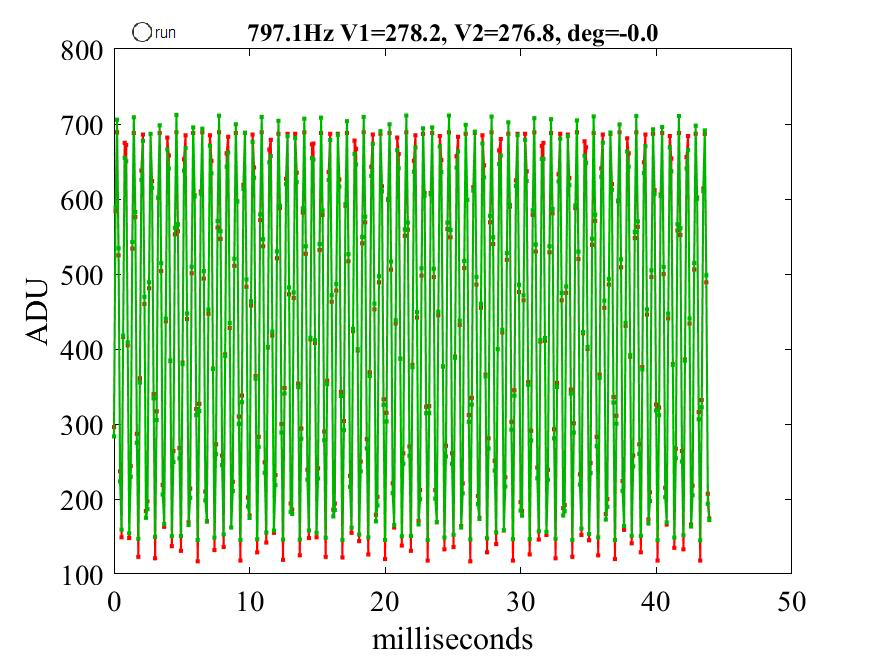

And the low end: 

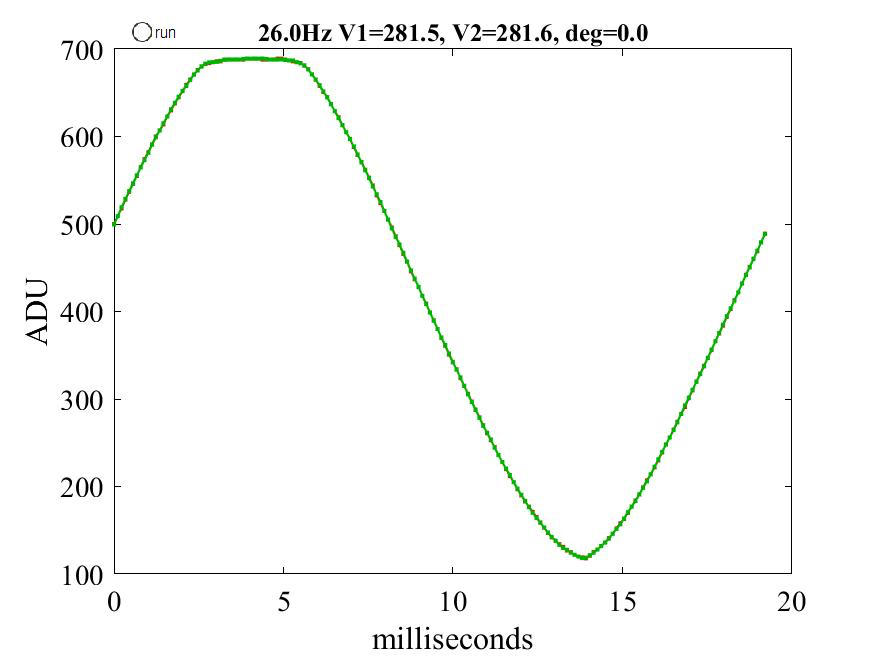

Below 26Hz, we often don't have enough data for a full period after trim. Significant distortion ("harmonic distortion") is evident the waveform, lowering the amplitude a little is the solution: 

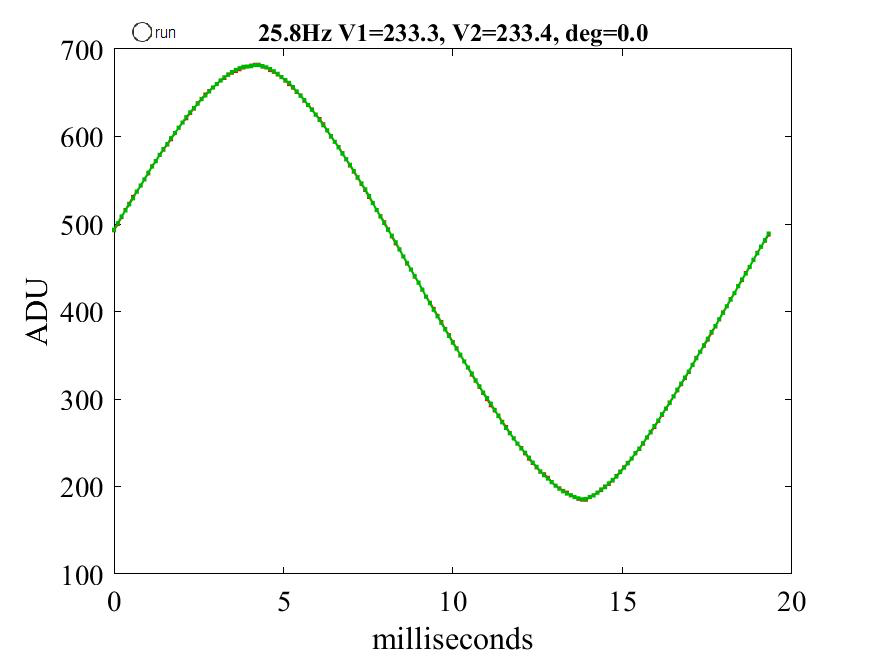

## Discussion

Over a wide range of frequencies (~26-800Hz), the amplitudes of the channels yield the same amplitudes, which are within 1% agreement with the Aneng meter. Frequencies agree between Arduino and Aneng, and the phases of the same waveforms are always zero. Suspicious that there was some error with phase always zero, I commented out the spline line (% `data(:,2) = spline(tt+.5, data(:,2), tt);`) and ran the code. At (arbitrary) 444Hz, the phase shift was 17.9deg. Is this what we'd predict? 

T = 1/444*1e6; % period in microseconds = 360 degrees

Elapsed time is 28.494501 seconds.


dPhase = 112/T*360

CV of A0=0.0019, A1=0.0019 frequency = 0.0207


Agreement doesn't get closer. This level of accuracy and precision suggests this apparatus is ready to measure amplitudes and phases in circuits.

We covered a lot of intellectual ground in this activity, and I encourage you to reflect on what you've learned, and jot down some additional questions and notes. 

Our Arduino and Matlab running this code perform the main function of a 2-channel oscilloscope, plotting voltage vs. time. Commercial oscilloscopes offer multiple voltage gains and protect the input from higher voltages. They offer easily adjustable time/division control on the horizontal axis -- which we could slow down with a  delay, but unfortunately we can't speed up very much with an Arduino (there actually are much faster 8 bit alternatives to analogRead, but the code I found with google is in assembly). The $4 Raspberry pi Pico microcontroller is ~20x faster, and Teensy microcontrollers have much faster ADCs capable of 16 bit. Modern oscilloscopes sample voltages billions of times per second, vs. our meager 8.9 thousand times per second, which still blows away human capabilities. So it behoves us to learn how to utilize automated data acquisition and reduction, because manual data acquisition and reduction has become largely obsolete -- computers have beaten us, just as calculators beat us for pencil and paper arithmetic. Instead of dwelling on our oscilloscope's shortcomings, consider positive aspects of its performance. Notice how stable and similar the mrms amplitudes of A0 and A1 are, and also how stable the frequency is. Let's quantify this a little by computing the coeficient of variance (= standard deviation / mean) of the amplitudes and frequency with 100 measurements. Turning the amplitude to 12'oclock, (f~300Hz), 

tic;

interchannel difference = -0.000118067


for k=1:100
    runOnce = true; 
    oscope3; 
    freqs(k) = sr/(length(td)/npds);
    ampls(k,:) = mrms(data);
end
toc
fprintf('CV of A0=%.4f, A1=%.4f frequency = %.4f\n',  ...
    std(ampls) ./ mean(ampls), std(freqs)/mean(freqs))
fprintf('interchannel difference = %g\n',diff(mean(ampls))/mean(mean(ampls)))



So the short term (over 25 seconds) amplitude stability is better than 0.2 percent (2 parts per thousand), and the mean amplitudes of A0 and A1 agree with each other to 100 parts per million (ppm). This is better than most osclloscopes which use 8 bit ADCs (ours is 10 bit). 

Some notable lessons I think are:

- We learned how to format and move binary data. 

- We saw harmonic distortion at full amplitude, where the waveform clearly deviated from sinusoidal. 

- We learned how to add graphical user interface (GUI) controls like buttons to a figure window and link them to code through callbacks. 

- We saw how the object oriented nature of these GUI elements can be discovered and manipulated. I didn't mention, but `get` and `set` are two powerful functions for probing inside and tweaking such objects. 

- We used `exist() and isvalid() `to keep initialization code in the same file as execution code, when its easier to see the two together. 

- % We used `profile` to find which code components were slow. 

- We implemented a simple algorithm in trim.m for finding positive-sloped zero crossings in (low-noise) data and the number of periods in the trimmed data. Many languages don't permit functions to return more than one result. 

- We used nargout to return more than one variable (many computer languages don't permit functions to return multiple values, although structures and objects provide a work-around.)

- We learned about temporal skewing that happens when 2 analog inputs are multiplexed to one analog-to-digital converter (ADC), and used a spline to deskew this systematic error, virtually eliminating it. This is the great thing about systematic errors -- that you can build a new "system" that corrects or negates them. That correction is impossible with random errors because predicting noise is by definition an oxymoron. 

## Conclusions

We've meticulously validated an apparatus capable of precise measurements of frequency, amplitude, and phase of sine waves from ~26-800Hz. We could extend the low end of the frequences by reducing the sample rate (adding `delay() `in the Arduino acquisition loop) -- since Arduino memory limits us to ~400 samples/channel. The high end is limited by the ADC  sample rate. The *processes* we've used to validate the system should be similar for any system -- even expensive ones. Sure, if an instrument costs thousands of dollars, you are more likely to *assume* it works accurately and precisely, but cost should never supercede empirical evidence in science. And (in my world), the reason to buy expensive apparatus is to push it against *its* limits. So validation is *always* important. 